warning off
data = readtable('C:\Users\malee\Downloads\archive\voice.csv')

data = 3168×21 table
    meanfreq       sd        median        Q25         Q75         IQR        skew       kurt     sp_ent       sfm        mode      centroid    meanfun      minfun     maxfun      meandom      mindom       maxdom       dfrange     modindx      label  
    ________    ________    ________    _________    ________    ________    _______    ______    _______    _______    ________    ________    ________

DataC=data;
 %Checking the Null values
 disp(sum(ismissing(data)));

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



 % Labeling our data with (1 for Male and 0 for Female) 
k=["male","female"];
 l=[1,0];
 g=DataC.label;
 % generete vector of 0 and 1 values 
number=zeros(length(g),1);
 for i=1:length(k)
 rs=ismember(g,k(i)); number(rs)=l(i);
 end
 DataC.label=number;

 %Dividing data into train & test set
 cv = cvpartition(size(DataC,1),'HoldOut',0.2);
 idx = cv.test;
 % Separate to training and test data
 dataTrain = DataC(~idx,:);
 Training_Data=dataTrain(:,1:end-1);
 Class_Label_Training=dataTrain(:,end);
 dataTest = DataC(idx,:);
 Testing_Data=dataTest(:,1:end-1);
 Class_Label_Testing=dataTest(:,end);
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 %Standardization of Training data
 m = table2array(Training_Data);
 meanArray = mean(m);
 stdArray = std(m);
 zam= (m - meanArray) ./ stdArray;
 Training_Data = array2table(zam, 'VariableNames',{'meanfreq' 'sd' 'median'...
 'Q25' 'Q75' 'IQR' 'skew' 'kurt' 'sp_ent' ...
 'sfm' 'mode' 'centroid' 'meanfun' 'minfun' 'maxfun' ...
 'meandom' 'mindom' 'maxdom' 'dfrange' 'modindx'});
 dataTrain=[Training_Data Class_Label_Training];

  %Standardization of Test data
 m = table2array(Testing_Data);
 meanArray = mean(m)

meanArray =     0.1802    0.0575    0.1851    0.1394    0.2240    0.0846    3.2326   39.2576    0.8956    0.4115    0.1651    0.1802    0.1435    0.0360    0.2594    0.8515    0.0565    5.1131    5.0567    0.1730


 stdArray = std(m)

stdArray =     0.0302    0.0171    0.0363    0.0503    0.0230    0.0439    4.3697  142.1733    0.0456    0.1797    0.0765    0.0302    0.0323    0.0180    0.0307    0.5582    0.0658    3.4926    3.4939    0.1183


 Testing_Data= (m - meanArray) ./ stdArray;
 Testing_Data = array2table(Testing_Data,'VariableNames',{'meanfreq' 'sd' 'median'...
 'Q25' 'Q75' 'IQR' 'skew' 'kurt' 'sp_ent' ...
 'sfm' 'mode' 'centroid' 'meanfun' 'minfun' 'maxfun' ...
 'meandom' 'mindom' 'maxdom' 'dfrange' 'modindx'});
 dataTest=[Testing_Data Class_Label_Testing];

 %Training the model
 K=3;
 % modelformed=fitcknn(dataTrain,'label');
 modelformed=fitcknn(Training_Data,Class_Label_Training, 'NumNeighbors',K);
 %Accuracy with default model parameters
 mk=predict(modelformed,Testing_Data);
 accuracy_check=((sum((mk==table2array(dataTest(:,end)))))/size(dataTest,1))*100;
 disp(accuracy_check);

   97.3144



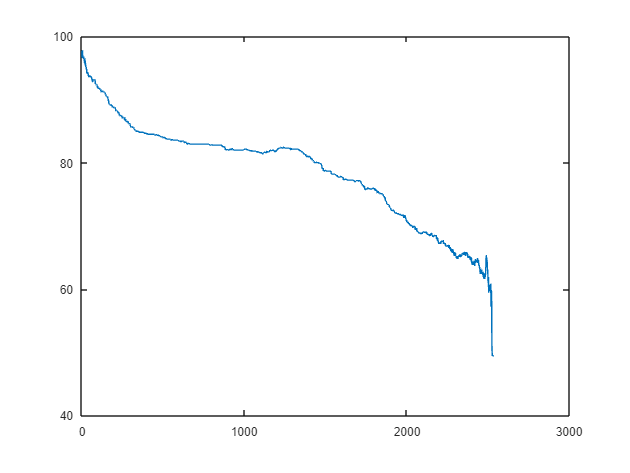

 %Running KNN for every possible value on this dataset
 accuracy=[];
 k=1;
 for i=1:size(dataTrain,1)
 modelformed=fitcknn(Training_Data,Class_Label_Training,'NumNeighbors',k);
 modelformed.NumNeighbors=i;
 mk=predict(modelformed,Testing_Data);
 accuracy_check=((sum((mk==table2array(dataTest(:,end)))))/size(dataTest,1))*100;
 accuracy=[accuracy accuracy_check];
 end
 %Plot 
plot((1:size(dataTrain,1)),accuracy);



% Load Fisher Iris data
load fisheriris;

% Combine the features and labels into a table
data = table(meas(:,1), meas(:,2), meas(:,3), meas(:,4), species, 'VariableNames', {'SepalLength', 'SepalWidth', 'PetalLength', 'PetalWidth', 'Species'});

% Initialize K to your chosen number of neighbors
K = 3;

% Prepare the training and testing data
cv = cvpartition(size(data, 1), 'HoldOut', 0.2);
idx = cv.test;

% Separate training and testing data
dataTrain = data(~idx, :);
dataTest = data(idx, :);

% Standardization of Training data
mTrain = table2array(dataTrain(:, 1:end-1));
meanArrayTrain = mean(mTrain);
stdArrayTrain = std(mTrain);
zamTrain = (mTrain - meanArrayTrain) ./ stdArrayTrain;
dataTrain(:, 1:end-1) = array2table(zamTrain, 'VariableNames', dataTrain.Properties.VariableNames(1:end-1));

% Standardization of Test data
mTest = table2array(dataTest(:, 1:end-1));
meanArrayTest = mean(mTest);
stdArrayTest = std(mTest);
zamTest = (mTest - meanArrayTest) ./ stdArrayTest;
dataTest(:, 1:end-1) = array2table(zamTest, 'VariableNames', dataTest.Properties.VariableNames(1:end-1));

% Convert species to categorical
dataTrain.Species = categorical(dataTrain.Species);
dataTest.Species = categorical(dataTest.Species);

% Training the K-NN model
modelformed = fitcknn(dataTrain(:, 1:end-1), dataTrain.Species, 'NumNeighbors', K);

% Testing the model
predictions = predict(modelformed, dataTest(:, 1:end-1));

% Calculate the accuracy
accuracy = sum(predictions == dataTest.Species) / size(dataTest, 1) * 100;

% Report the optimal K value (you can modify this section based on your needs)
fprintf('Accuracy with K=%d: %.2f%%\n', K, accuracy);

Accuracy with K=3: 96.67%
